clc % clear command window
clear all % clear workspace

1. Supply path to the toolkit's "model_code" directory to "cfg" structure, and add the "common" subfolder to the MATLAB path. Also specify the general directory where results will be saved. 

% Add paths to relevant functions
cfg.model_dir = '/Shared/boeslab/Users/jcgriffis/ibb_modeling_toolkit/model_code'; % path to toolkit
addpath(genpath(fullfile(cfg.model_dir, 'common'))); % add common folder to path

% Specify output directory (Note - output folders for specific analyses will be created in this directory)
out_dir = '/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/tutorial_results'; 

2. To perform a lesion-mapping/lesion-modeling analysis, specify that the modality is "lesion", and supply a path to a brain mask that is 

co-registered to the same template as your lesion data and that has the same image and voxel dimensions as your lesion data.

% Specify data modality and supply brain mask
cfg.modality = 'lesion'; % predictor modality - 'lesion' or 'other' 
cfg.mask_path = fullfile('/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Lesion_3mm/mask/brain_mask.nii'); % path to brain mask

3. Specify general modeling options.

- cfg.model_spec - the type of model you want to fit. To fit a radial basis function kernel support vector classifier, set to 'kernsvc'.

- cfg.fit_explanatory_model - flag indicating whether you want to fit a model to the full dataset to test significance of model coefficients. For inferential (e.g., lesion-symptom mapping) analyses, turn this on. Note that the model is explanatory, not predictive. 

- cfg.optimize_hyperparams - flag indicating whether you want to use cross-validation to optimize model hyper-parameters. For multivariate models, this is recommended.

- cfg.cross_validation - flag indicating whether you want to use cross-validation to estimate predictive performance and out-of-sample generalization. If hyper-parameter optimization is selected, then this will perform nested cross-validation. For predictive analyses, turn this on. Note that significance testing is not performed on model coefficients/maps. 

- cfg.bootstrap - flag indicating whether you want to use bootstrapping to estimate statistical significance of model coefficients and/or to estimate confidence intervals for multivariate explanatory models. Recommended if fitting multivariate explanatory model.

- cfg.permutation - flag indicating whether you want to use permutation testing to estimate statistical significance of model fit and/or model coefficients.

- Note - Cross-validation testing and/or permutation testing is recommended to test for the significance of multivariate models.

These options will be used to initialize an analysis with default parameters for the selected options by supplying the cfg struct as an input to the function get_default_model_cfg(), which automatically populates the cfg structure with default settings for the specified modeling options, and returns the populated cfg structure. 

% Specify general modeling options
cfg.model_spec = 'kernsvc'; % model to fit
cfg.fit_explanatory_model = 1; % fit explanatory model to full dataset 
cfg.optimize_hyperparams = 1; % use cross-validation to optimize model hyperparameters
cfg.cross_validation = 1; % use cross-validation to perform significance testing and estimate out-of-sample prediction performance
cfg.bootstrap = 1; % use bootstrap resampling for significance testing of explanatory model coefficients
cfg.permutation = 1; % use permutation testing for significance testing of explanatory model fit 

% Initialize cfg file with default settings given general modeling options
cfg = get_default_model_cfg(cfg); 

cfg.jackknife field is empty; setting to 0 with default settings
Analysis type is lesion - setting defaults


4. Specify paths to behavioral and lesion data, and load and format data into predictor matrix and response array. The behavioral CSV file should include a "study_id" column containing patient IDs and a second column containing behavioal scores. Also specify the path to the directory containing the lesion images. Lesion images for all patients should be in the same folder. Note: IDs in "study_id" column must match file prefixes for lesion data - e.g., if the "study_id" for patient 1 is "0001", then their lesion file should be "0001.nii.gz".

The function get_and_format_lesion_data() adds several fields to the cfg structure: 

- cfg.X - subject-by-voxel lesion predictor matrix 

- cfg.lvol - subject-by-1 array of lesion volumes

- cfg.Y - subject-by-1 array of behavioral scores

- cfg.include_subs - string array of subject IDs that had non-missing behavioral data and that were included in the analysis.

- cfg.include_inds - indices of included subjects in original ID array

Note - for classification analyses, it is expected that the groups labels will be coded with numerical values of 1 and -1, respectively. 

% Specify path to CSV containing study IDs and behavioral scores
beh_csv = readtable('/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/behavior/test_data.csv'); % read in CSV file as table
id_col = 'study_id'; % name of column containing 4-digit IDs
beh_col = 'mae_token'; % name of column containing behavior of interest

% Specify lesion directory and indicate whether patients are registry patients
lesion_dir = '/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Lesion_3mm'; % directory containing lesion images
registry_flag = 1; % CSV contains numeric registry IDs (i.e., '0's need to be appended for subjects < 1000)

% Get formatted lesion matrix, behavioral data, subject IDs, and mask volume/header and in-mask indices and store in cfg
cfg = get_and_format_lesion_data(beh_csv, id_col, beh_col, registry_flag, lesion_dir, cfg);

All subjects with behavioral data have lesion files, N=282 patients will be included


% Recode outcome into categorical for his tutorial
cfg.Y = cfg.Y .* -1; 
cat_Y = zeros(length(cfg.Y),1);
cat_Y(cfg.Y >= -38) = 1;
cat_Y(cfg.Y < -38) = -1;
cfg.Y = cat_Y;

5. Modify any default settings as relevant to the analysis. Here, we increase the lesion frequency threshold for voxel inclusion from the default (4) to 10, set the "DTLVC" option to off, set the number of permutation and bootstrap iterations for testing the inferential model and coefficients, and set the number of folds and repeats used for hyper-parameter optimization and cross-validation. We also specify that we want to stratify train/test splits based on the outcome variable distribution and indicate that we want this to be a "stackable" prediction model, so we don't want to drop subjects that only have zero-valued predictor data. See the function get_default_model_cfg() for all default parameter values. 

% Customize analysis parameters

% Specify misclassification cost for each class
cfg.cost = [0,2.3;1,0]; % Set missclassification cost for positive class to twice that of the negative class

% Lesion-mapping
cfg.freq_thresh = 10; % only include voxels that are lesioned in at least 10 patients
cfg.dtlvc = 0; % Use direct total lesion volume control (Zhang et al., 2014)

% Statistical significance testing 
cfg.perm.n_perm = 1000; % permutation iterations for testing on in-sample model fit
cfg.boot.n_boot = 1000; % bootstrap iterations for testing on model coefficients

% Hyper-parameter optimization
cfg.hp_opt.cv_type = 'KFold'; % Do K-fold cross-validation for hyper-parameter optimization
cfg.hp_opt.folds = 2; % 2-fold cross-validation (to speed up analysis)
cfg.hp_opt.repeats = 5; % 5 repeats of 2-fold cross-validation

% Cross-validation
cfg.cv.cv_type = 'KFold'; % Do K-Fold cross-validation
cfg.cv.folds = 5; % 5-fold cross-validation
cfg.cv.repeats = 5; % 5 runs of 5-fold cross-validation
cfg.cv.permutation = 0; % Permutation testing of cross-validation (turned off for this tutorial to save time)
cfg.cv.n_perm = 0; % 0 permutations (at least 20 are recommended, this is the minimum to achieve p<0.05)
cfg.cv.stacked_model = 1; % Don't drop subjects with only zero-valued predictor data, and pre-generate train/test splits

% Stratification for cross-validation 
cfg.strat_var = cfg.Y; % stratify partitions for CV and hyper-parameter optimization according to group labels

6. Specify the specific folder where analysis results should be saved. Note - if the output folder specified in cfg.out_dir doesn't exist, it will be created automatically once the analysis is run.

% Specify output directory
cfg.out_dir = fullfile(out_dir, [cfg.model_spec '_' beh_col '_lesion_d' num2str(cfg.dtlvc)]);

7. Supply the fully-specified cfg structure as input to the function fit_and_evaluate_model(), which executes the modeling analysis specified in the cfg structure. This returns a new structure, model_results, which contains the results of the modeling analysis along with the original cfg file (as a sub-structure) for reproducibility. This structure is saved by default in the folder specified by cfg.out_dir. If cross-validation was performed, a second structure named cv_results, which contains the results of the cross-validation analyses, will be saved in the file "cv_results.mat" within the output directory specified by cfg.out_dir. 

Trimming data to retain columns with at least 10 observations greater than or equal to 1
Preallocating CV results
Outer CV repeats:1/5
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration
Starting parallel pool (parpool) using the 'Processes' profile ...


Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to the parallel pool (number of workers: 12).
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration
Outer CV repeats:2/5
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at eac

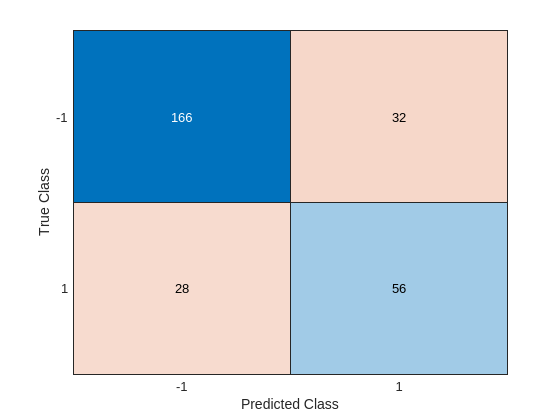

Full-sample Cross-Validation Fisher Exact Test: odds ratio=10.375, p=2.7409e-16
Full-sample Cross-Validation Test Classification Accuracy (Group = -1): 0.83838
Full-sample Cross-Validation Test Classification Accuracy (Group = +1): 0.66667
Full-sample Cross-Validation Test Area Under ROC Curve: 0.8058
Running KFold optimization for model hyperparameters
Number of folds: 2
Number of optimization iterations: 60
Repartitioning at each iteration


Permutation 5
Permutation 10
Permutation 15
Permutation 20
Permutation 25
Permutation 30
Permutation 35
Permutation 40
Permutation 45
Permutation 50
Permutation 55
Permutation 60
Permutation 4
Permutation 9
Permutation 14
Permutation 19
Permutation 24
Permutation 29
Permutation 34
Permutation 39
Permutation 44
Permutation 54
Permutation 59
Permutation 3
Permutation 8
Permutation 13
Permutation 18
Permutation 23
Permutation 22
Permutation 28
Permutation 33
Permutation 38
Permutation 49
Permutation 53
Permutation 58
Permutation 12
Permutation 17
Permutation 27
Permutation 32
Permutation 43
Permutation 48
Permutation 2
Permutation 1
Permutation 7
Permutation 6
Permutation 11
Permutation 16
Permutation 21
Permutation 26
Permutation 31
Permutation 37
Permutation 36
Permutation 42
Permutation 47
Permutation 52
Permutation 51
Permutation 57
Permutation 255
Permutation 254
Permutation 253
Permutation 41
Permutation 56
Permutation 99
Permutation 138
Permutation 177
Permutation 216
Permutation 2

% fit model with CV hyperparameter optimization and selected significance testing
[model_results] = fit_and_evaluate_model(cfg);

8. View model results structure to evaluate model performance measures. The different fields contain different details about analysis parameters, data, and results.

- has_data - logical array of length n_subjects with values of 1 for all patients that were included in the analysis. Some patients may have been dropped due to not having any data after removing voxels that met the minimum damage threshold, and this can be used to identify which patients were dropped and which patients were retained for the analysis. 

- hp_opt - hyper-parameter optimization struct

- C - BoxConstraint hyper-parameter

- gamma - KernelScale hyper-parameter

- roc_auc - the obsreved area under the ROC curve for the full inferential model 

- classrate - a 1x3 array containing classification rates: classrate(1) contains the classification rate for the group labeled "-1", classrate (2) contains the classification rate for the group labeled (1) , and classrate(3) contains the classification rate for all observations. 

- coeff - model coefficients (i.e., beta weights) for each voxel included in the model. 

- beta_0 - intercept of the model

- obs_y - observed group labels

- pred_y - fitted group labels from the full-sample model (i.e., within-sample model "predictions").

- pred_score - prediction score (used to determine pred_y) for the positive class (label = 1)

- opt_score_thresh - optimal score threshold obtained rom ROC analysis

- perm - subfield containing results from permutation testing

- boot - subfield containing results from bootstrap analyses

- X - final predictor matrix after trimming columns with insufficient data, in this case transformed by the DTLVC method.

- X_ind - indices mapping the columns in the final predictor matrix model_results.X to the colulmns in the original predictor matrix cfg.X, i.e., the columns included in model_results.X are given by: model_results.X = cfg.X(model_results.X_ind) 

- rng_seed - RNG seed and state for reproducibility

- cfg - the cfg structure containing analysis parameters and details for reproducibility

- methods_text - text description of methods details. Also saved as .txt file in output directory

- results_text - text description of results details. Also saved as .txt file in output directory

% View contents of model_results structure
model_results

model_results = struct with fields:
            has_data: [282×1 double]
              hp_opt: [1×1 struct]
                   C: 0.1369
               gamma: 63.8861
               alpha: [214×1 single]
               coeff: [13786×1 single]
             roc_auc: 0.8579
           classrate: [0.8788 0.6786 0.8191]
              pred_y: [282×1 double]
          pred_score: [282×1 single]
               obs_y: [282×1 double]
    opt_score_thresh: -0.1385
                perm: [1×1 struct]
                boot: [1×1 struct]
                   X: [282×13786 single]
               X_ind: [13786×1 double]
            rng_seed: {[0]  'twister'}
                 cfg: [1×1 struct]
        methods_text: 'Data were modeled using a support vector classification (SVC) model with a radial basis function (RBF) kernel. Only predictors with at least 10 non-zero observations with absolute values greater than 1 were included in the analysis. N=282 observations were included in the analysis. An inferenti

% View contents of .perm field:
model_results.perm

ans = struct with fields:
    model_pval: 0.0150


% View results of .boot field:
model_results.boot

ans = struct with fields:
            p_coeff: [13786×1 single]
            z_coeff: [13786×1 single]
         fdrp_coeff: [13786×1 single]
         fwep_coeff: [13786×1 single]
       classrate_ci: [2×3 single]
         roc_auc_ci: [2×1 single]
           coeff_ci: [2×13786 single]
    coeff_ci_thresh: [13786×1 single]


By accessing fields in the model_results structure, you can evaluate the fit of the explanatory model. Note - these are *not* prediction performance estimates because these are from the full-sample model, and can be influenced by over-fitting. Prediction performance estimates are in the cv_results structure saved into the output directory. We'll display several of the performance estimates along with the results of the permutation test. Note that the inferential model achieves perfect performance, which indicates overfitting.

% Display model fit for in-sample explanatory model
disp(['Classification Rate (Group = -1): ' num2str(model_results.classrate(1))]);

Classification Rate (Group = -1): 0.87879


disp(['Classification Rate (Group = 1): ' num2str(model_results.classrate(2))]);

Classification Rate (Group = 1): 0.67857


disp(['Classification Rate (Overall): ' num2str(model_results.classrate(3))]);

Classification Rate (Overall): 0.81915


disp(['Area under ROC Curve: ' num2str(model_results.roc_auc)]);

Area under ROC Curve: 0.85792


disp(['Permutation p-value (AUC): ' num2str(model_results.perm.model_pval)]);

Permutation p-value (AUC): 0.014985


% Evaluate 95% CIs from bootstrapping
disp(['95% CI on Group -1 Classification Rate: ' num2str(model_results.boot.classrate_ci(:,1)')]);

95% CI on Group -1 Classification Rate: 0.72507           1


disp(['95% CI on Group 1 Classification Rate: ' num2str(model_results.boot.classrate_ci(:,2)')]);

95% CI on Group 1 Classification Rate: 0.422     0.73535


disp(['95% CI on Overall Classification Rate: ' num2str(model_results.boot.classrate_ci(:,3)')]);

95% CI on Overall Classification Rate: 0.71314     0.85992


disp(['95% CI on AUC: ' num2str(model_results.boot.roc_auc_ci')]);

95% CI on AUC: 0.78295     0.86905


9. To evaluate *prediction* performance, load the cv_results.mat file from the output directory and view the contents.

- train_set - subject-by-repeat-by-fold matrix of 1's and 0's. For each pairing of repeat and fold (e.g., repeat 1 fold 3 would be train_set(:, 1, 3), patients included in the training set have values equal to 1, and patients not in the training set for that fold for that repeat have values equal to 0.

- test_set - subject-by-repeat-by-fold matrix of 1's and 0's. For each pairing of repeat and fold (e.g., repeat 1 fold 3 would be test_set(:, 1, 3), patients included in the test set have values equal to 1, and patients not in the test set for that fold for that repeat have values equal to 0.

- beta_0 - repeat-by-fold matrix of intercepts from the models fit to the training sets. Here, there was 1 repeat of 5-fold cross-validation, so beta_0 is a 1x5 array.

- avg - subfield containing model coefficients and performance estimates averaged across folds

- coeff - n_voxels-by-repeat-by-fold matrix of model coefficients, analogous to the corresponding field in model_results

- all - subfield containing out-of-sample predictions for all folds within each repeat along with a confusion matrix and Fisher Exact Test results computed from the mode (across repeats) out-of-sample predictions for all observations (i.e., collapsed across folds and repeats) 

- pred_y - n_subjects-by-repeat-by-fold matrix of predicted behavioral scores for each test set in each fold and each repeat. For each fold within each repeat, patients that were in the training set have values equal to NaN, while patients in the test set have values equal to their predicted behavioral scores. 

- obs_y - same as pred_y, but with observed scores.

- pred_score - an n_subject-by-n_repeats-by-n_folds matrix predicted scores for the positive class (label = 1)

- classrate - an n_repeats-by-n_folds-by-3 matrix containing classification rates: classrate(1) contains the classification rate for the group labeled "-1", classrate (2) contains the classification rate for the group labeled (1) , and classrate(3) contains the classification rate for all observations.  

- roc_auc - an n_repeats-by-n_folds matrix containing area under the ROC curve for each fold and repeat

- opt_thresh - optimal thresholds obtained from ROC analysis 

% Load cv_results to evaluate out-of-sample prediction
load(fullfile(cfg.out_dir, 'cv_results.mat'));
cv_results

cv_results = struct with fields:
     train_set: [282×5×5 double]
      test_set: [282×5×5 double]
             C: [5×5 double]
         gamma: [5×5 double]
         alpha: [5×5 double]
           avg: [1×1 struct]
         coeff: [13786×5×5 double]
           all: [1×1 struct]
        pred_y: [282×5×5 double]
         obs_y: [282×5×5 double]
    pred_score: [282×5×5 double]
     classrate: [5×5×3 double]
       roc_auc: [5×5 double]
    opt_thresh: [5×5 double]
        hp_opt: [1×1 struct]
         opt_c: [5×5 single]
         opt_g: [5×5 double]


% Check .all subfield
cv_results.all

ans = struct with fields:
         pred_y: [282×5 double]
          obs_y: [282×1 double]
     pred_score: [282×5 double]
      confusion: [1×1 ConfusionMatrixChart]
    fisher_pval: 2.7409e-16
    fisher_stat: [1×1 struct]
      classrate: [0.8384 0.6667]
        roc_auc: 0.8058


% Confusion matrix
cv_results.all.confusion.NormalizedValues

ans =    166    32
    28    56


% Fisher's Exact Test
cv_results.all.fisher_stat

ans = struct with fields:
             OddsRatio: 10.3750
    ConfidenceInterval: [5.7469 18.7303]


We can plot the performance for the held-out patients across folds of the cross-validation. Note that while performance is good, the cross-validation results are much less optimistic than the results of the inferential model. 

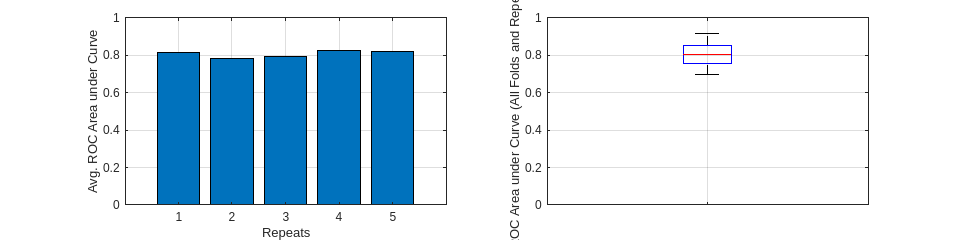

% Plot performance
clf;
subplot(1,2,2);
boxplot(cv_results.roc_auc(:)); grid on;
hold on; ylabel('ROC Area under Curve (All Folds and Repeats)');
set(gca, 'YLim', [0, 1]); set(gca, 'XtickLabel', '');
subplot(1,2,1);
bar(cv_results.avg.roc_auc);
set(gca, 'XtickLabel', {'1','2','3','4','5'});
xlabel('Repeats'); grid on;
ylabel('Avg. ROC Area under Curve');
axis([0, 6, 0, 1]);
set(gcf, 'position', [0, 0, 1000, 250]); grid on;

9. Save explanatory model coefficients as NIFTI images (i.e., as lesion-symptom maps). NIFTI images containing model coefficients will be saved in the output directory specified by cfg.out_dir. If bootstrapping and/or permutation testing was performed for model weights, then result images will be saved into sub-folders named "Bootstrap_Result_Images" and "Permutation_Result_Images", respectively. 

% Map model coefficients back to the in-brain voxels of the 3D MNI volume using MATLAB NIFTI I/O functions
disp('Saving beta weight maps as NIFTI images...');

Saving beta weight maps as NIFTI images...


write_model_weight_maps(model_results);

    0.0500



disp('Done')

Done
